#  NLab 1: Cartesian trajectory planning

This exercise illustrates the generation of Cartesian trajectories using one of the methodologies studied in this course. For this purpose, a series of functions will be used:

## Matlab functions

- `cartesian_planning`: Script that performs the complete simulation during all proposed segments, using the Robotic Toolbox with the ABB IRB120 manipulator model and the graphical representation of the temporal evolution of Cartesian trajectories and orientation in ZYZ*Z**Y**Z* Euler angles.

% Lab 1: Cartesian trajectory planning
clearvars

P0=[1 0 0 0.3740; 0 1 0 0; 0 0 1 0.6300; 0 0 0 1];
P1=[0 0 1 0.3038; 0 1 0 0; -1 0 0 0.0510; 0 0 0 1];
P2=[0 -1 0 0; 0 0 1 0.3020; -1 0 0 0.5580; 0 0 0 1];

tau=1;
T=10;

### 1. Quaternion interpolation

Define the quaternion interpolation function based on the Taylor method `[pr, qr]=qpinter(P1, P2, lambda)`that calculates the intermediate quaternion between *q*1 (initial) and *q*2 (final). The value λ must satisfy 0≤*λ*≤1, so that `[p1, q1]=qpinter(P1, P2, 0)` and `[p2, q2]=qpinter(P1, P2, 1)`.

%% Exercise 1: Cartesian interpolation

[p0, q0]=qpinter(P0, P1, 0)  

p0 =     1.0000         0         0    0.3740
         0    1.0000         0         0
         0         0    1.0000    0.6300
         0         0         0    1.0000


q0 =      1     0     0     0


[p1, q1]=qpinter(P0, P1, 1)

p1 =          0         0    1.0000    0.3038
         0    1.0000         0         0
   -1.0000         0         0    0.0510
         0         0         0    1.0000


q1 =     0.7071         0    0.7071         0


[p05, q05]=qpinter(P0, P1, 0.5)

p05 =     0.5000         0    0.5000    0.3389
         0    1.0000         0         0
   -0.5000         0    0.5000    0.3405
         0         0         0    1.0000


q05 =     0.9239         0    0.3827         0


### 2. Smooth trajectory generation

Create a MATLAB function in the format `P=generate_smooth_path(P0, P1, P2, tau, T, t)` that calculates the transformation *P* corresponding to the movement from *P*0 to *P*2 via *P*1 smoothed by the Taylor method. The parameters *τ* and *T* correspond respectively to the transition interval and total time used to traverse the path as shown in Figure 1, and *T* indicates the time at which the location of the calculated path *P* is reached.

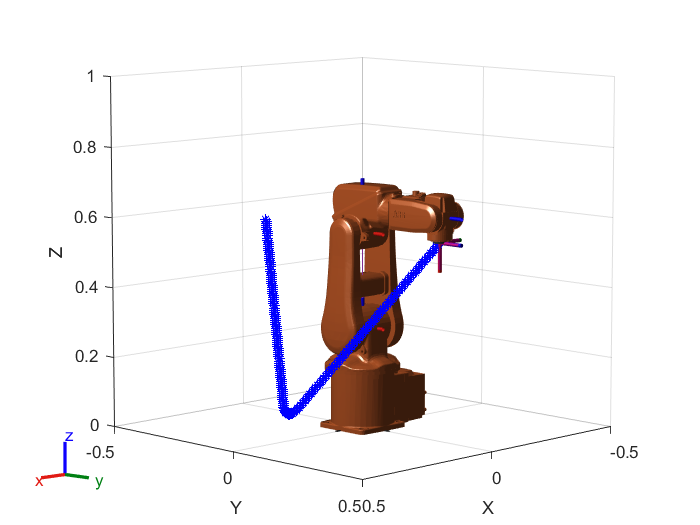

%% Exercise 2: Smooth trajectory generation

% Load ABB IRB120 model
[IRB120, IRB120Data] = loadrobot('abbIrb120','DataFormat','row','Gravity',[0 0 -9.81]);
Home=IRB120.homeConfiguration; % Use home position as start setting for inverser kinematics
% Create object for inverse kinematics
ik_IRB120 = inverseKinematics('RigidBodyTree', IRB120); 
% Tolerances
weights=[0.25 0.25 0.25 1 1 1];
% Create figure to represent the manipulator
f1=figure(1);
set(f1,'Name','Manipulador');

% Calculate the interpolation for the whole segment
x=[]; y=[]; z=[]; alfa=[]; beta=[]; gamma=[];
for t=-T:0.1:T
    % Call the function to generate the smoothed cartesian path
    [P,Q]=generate_smooth_path(P0,P1,P2,tau,T,t); 
    x=[x P(1)];
    y=[y P(2)];
    z=[z P(3)];

    Tq=q2tr(Q);
    Tq(1:3,4)=[P(1) P(2) P(3)]'; % Complete homogeneous transofrmation matrix
    ZYZ=tr2zyz(Tq);

    alfa=[alfa,ZYZ(1)];
    beta=[beta,ZYZ(2)];
    gamma=[gamma,ZYZ(3)];

    % Get position and orientation in joint space (ik)
    [robot_pose, solnInfo]=ik_IRB120('tool0',Tq, weights, Home);
    % Represent each configuration of the robot
    ax=show(IRB120, robot_pose); axis([-0.5,0.5,-0.5,0.5,0,1]);   
     hold on
     plot3(ax, x, y, z, 'b*')  
     hold off
    drawnow
end

### 3. Graphical representation

Plot the evolution of position and orientation (in ZYZ Euler angles) throughout the trajectory.

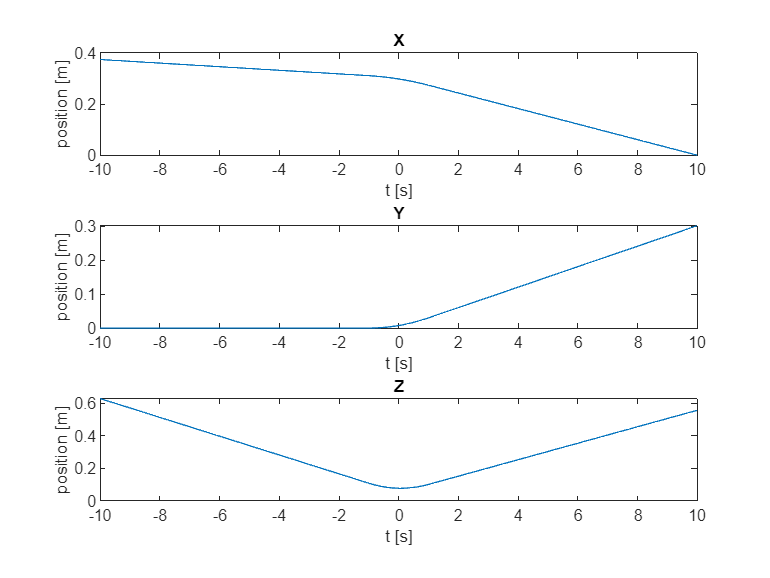

%% Exercise 3: Graphical representation

% Represent cartesian position
t=-T:0.1:T;
f2=figure(2);
set(f2,'Name','Cartesian position');
subplot(3,1,1),plot(t,x);title('X');xlabel('t [s]'); ylabel('position [m]');
subplot(3,1,2),plot(t,y);title('Y');xlabel('t [s]'); ylabel('position [m]');
subplot(3,1,3),plot(t,z);title('Z');xlabel('t [s]'); ylabel('position [m]');

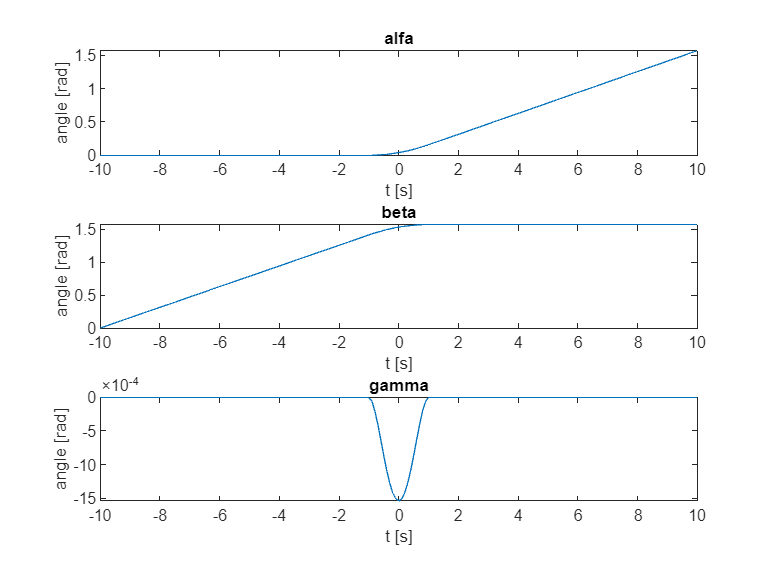


% Represent cartesian orientation as Euler angles
f3=figure(3);
set(f3,'Name','Ángulos de Euler');
subplot(3,1,1),plot(t,alfa);title('alfa');xlabel('t [s]'); ylabel('angle [rad]');
subplot(3,1,2),plot(t,beta);title('beta');xlabel('t [s]'); ylabel('angle [rad]');
subplot(3,1,3),plot(t,gamma);title('gamma');xlabel('t [s]'); ylabel('angle [rad]');

## Functions

function [pr,qr]=qpinter(Pa,Pb,lambda)
% Calculate the position pr and the orientation with the quaternion qr of
% the interpolated positon between Pa & Pb at lambda·100% of the trayectory

    % Interpolate the position
    pr = Pa + lambda*(Pb-Pa);

    % Interpolate the orientation
    qA = tr2q(Pa);
    qB = tr2q(Pb);

    % The 3D rotation from qA to qB 
    qC = qqmul(qinv(qA),qB);

    % qC = [Wc, Vc]
    Wc = qC(1);
    Vc = qC(2:4);

    % With Wc & Vc get theta & n. Theta is the angle rotated & n is the
    % axis of the rotation. The good thing of cuaternions is that n is
    % constant
    thetaC = 2*acos(Wc);
    n = Vc / sin(thetaC/2);

    % The interpolated theta depends on lambda
    thetaR = lambda*thetaC;

    % With thetaR & n we calculate the new velocities
    Wr = cos(thetaR/2);
    Vr = n*sin(thetaR/2);

    % Interpolate the orientation for the rotation
    qrot = [Wr, Vr];

    % Finally the rotation
    qr = qqmul(qA, qrot);

end

function [P, Q]=generate_smooth_path(P1, P2, P3, tau, T, t)
    % Function that calculates the transformation (P - position, and Q - orientation) from P1 to P3 smoothing in P2 with Taylor method (quaternions)

    if (t<-T || t>T)
        % Out of allowed range
        disp('Parameter t out of range');
    else

        if (t<=-tau) % First segment (lineal)
            % We can reuse the previous function, we need lambda
            lambda = (t+T)/T;
            [P, Q] = qpinter(P1, P2, lambda);
            P = P(1:3, 4);
            
        elseif (t>=tau) % Third segment (lineal)
            lambda = t/T;
            [P, Q] = qpinter(P2, P3, lambda);
            P = P(1:3, 4);
            
        else % Second segment (smoothing)
            % In this segment we have two lambda
            lambda1 = -(tau-t)^2/(4*tau*T);
            lambda2 = (tau+t)^2/(4*tau*T);

            p1 = P1(1:3, 4);
            q1 = tr2q(P1);
            p2 = P2(1:3, 4);
            q2 = tr2q(P2);
            p3 = P3(1:3, 4);
            q3 = tr2q(P3);

            % Position interpolation
            P = p2 + lambda1*(p2-p1) + lambda2*(p3-p2);            

            % Orientation interpolation
            q12 = qqmul(qinv(q1), q2);
            theta12 = 2*acos(q12(1));
            n12 = q12(2:4)/sin(theta12/2);

            thetak1 = lambda1*theta12;
            qk1 = [cos(thetak1/2), n12*sin(thetak1/2)];

            q23 = qqmul(qinv(q2), q3);
            theta23 = 2*acos(q23(1));
            n23 = q23(2:4)/sin(theta23/2);

            thetak2 = lambda2*theta23;
            qk2 = [cos(thetak2/2), n23*sin(thetak2/2)];

            Q = qqmul(q2, qqmul(qk1, qk2));
            
        end
    end
end